# MECH 513 — Lab 7: Surrogate Modeling (RSM & ANN)

% Author: Hector Hernandez
% Purpose: Walk through surrogate modeling for a costly CFD sub-simulation.
% Notes:
%   • Critical lines are intentionally missing (marked TODO).
%   • Task 3 (optimization) is comments only.

clc; clear; close all; format compact;


## 0) Setup & problem bounds

% The CFD "truth" model (expensive) takes x = [x1, x2] in ranges:
%   x1 ∈ [-2, 2],  x2 ∈ [-1, 1]
% We'll build two surrogates: a quadratic RSM and a small ANN.

% (Optional) Make randomness reproducible:
rng(513)  % <-- uncomment if you want reproducibility

x1_min = -2; x1_max =  2;
x2_min = -1; x2_max =  1;


## 1) Design of Experiments (DOE) — generate inputs & run CFD

% % Goal: produce a dataset (inputs, outputs) that covers the design space.
% % Use ~100 points (or more) to expose curvature and interactions.
% 
% % ---- Choose a DOE strategy (example: uniform grid) ----
% numsamples = 10;                  % 10x10 grid => 100 points
% 
% x1_vector = -2 + 4*rand(numsamples,1);
% x2_vector = -1 + 2*rand(numsamples,1);
% 
% index = 0;
% 
% % Preallocate storage
% inputs = zeros(numsamples^2, 2);
% outputs = zeros(numsamples^2, 1);
% 
% % ---- Evaluate the expensive CFD model on the DOE ----
% for i = 1:length(x1_vector)
%     for j = 1:length(x2_vector)
%         index = index + 1;
%         inputs(index,1:2) = [x1_vector(i) x2_vector(j)];
%         outputs(index,1) = giant_CFD_code([x1_vector(i) x2_vector(j)]);
%     end
% end
% 
% % Save raw dataset for reuse
% save('CFDresults.mat','inputs','outputs')


## 2) Split data into Training / Validation / Testing

% Target split: ~70% train, 15% validation, 15% test.

load('CFDresults.mat','inputs','outputs')
N = size(inputs,1);
% TODO: create a random permutation of 1:N and split indices by the ratios
p = randperm(N);            % TODO
Ntr = round(0.70*N);        % TODO
Nv  = round(0.15*N);        % TODO
Nt  = N - Ntr - Nv;         % TODO

idx_tr = p(1:Ntr);          % TODO
idx_v  = p(Ntr+1 : Ntr+Nv);          % TODO
idx_te = p(Ntr+Nv+1 : end);          % TODO

training_data_input  = inputs(idx_tr, :);   % TODO
training_data_output = outputs(idx_tr, :);  % TODO
validation_data_input  = inputs(idx_v, :);  % TODO
validation_data_output = outputs(idx_v, :); % TODO
testing_data_input   = inputs(idx_te, :);   % TODO
testing_data_output  = outputs(idx_te, :);  % TODO

disp('Data partitioned successfully.');

Data partitioned successfully.


## 3) Task 1 — Response Surface Modeling (RSM): Fit a full quadratic

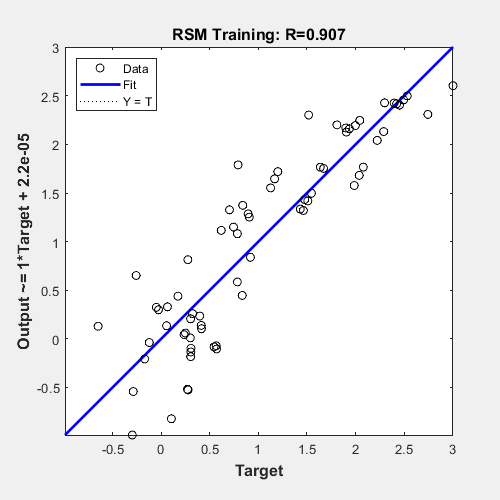

% Canonical quadratic in 2D:
%   y = β0 + β1 x1 + β2 x2 + β3 x1 x2 + β4 x1^2 + β5 x2^2
% Use MATLAB's rstool interactively:  >> rstool(X_train, y_train, 'quadratic')
% • Explore the profiler
% • Export fitted coefficients to the workspace as "beta" (1x6) or save to .mat

% --- After using rstool, ensure you have beta available: ---
% ex: load('Lab7Betas.mat','beta')   % Optional if you saved betas
beta = [0.2141, 0.2681, 0.2402, 0.8822, 0.8058, -0.7864]; % TODO: paste your β values here if not loading

% Make an evaluator for the quadratic surface:
rsm_fun = @(x1,x2,b) b(1) + b(2).*x1 + b(3).*x2 + b(4).*x1.*x2 + b(5).*x1.^2 + b(6).*x2.^2;

% ---- Evaluate RSM on each split (vectorized) ----
RSMPred_training   = rsm_fun( training_data_input(:,1),   training_data_input(:,2),   beta ); % TODO
RSMPred_validation = rsm_fun( validation_data_input(:,1), validation_data_input(:,2), beta ); % TODO
RSMPred_testing    = rsm_fun( testing_data_input(:,1),    testing_data_input(:,2),    beta ); % TODO

% ---- Quick regression visual check (pred vs true) ----
figure; plotregression(RSMPred_training,   training_data_output,   'RSM Training');     % TODO

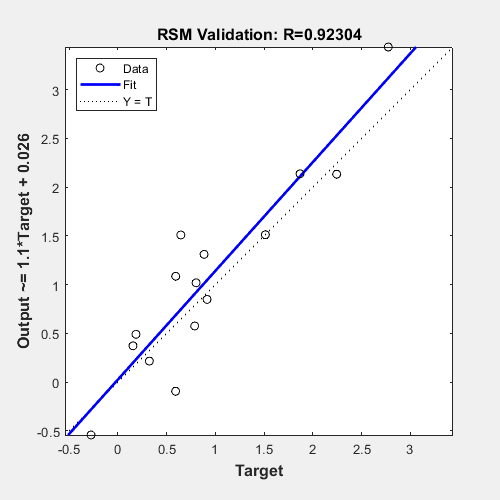

figure; plotregression(RSMPred_validation, validation_data_output, 'RSM Validation');   % TODO

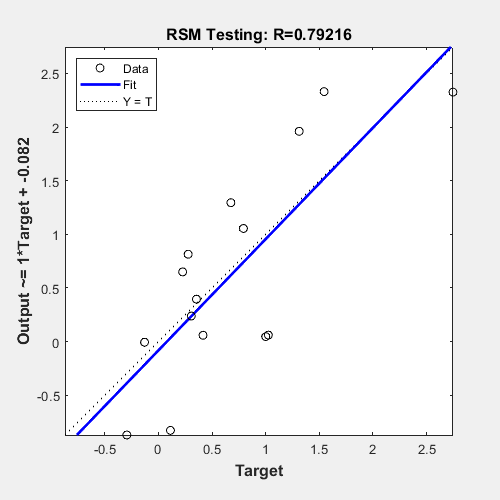

figure; plotregression(RSMPred_testing,    testing_data_output,    'RSM Testing');      % TODO


% ---- Error metrics (Validation set) ----
rmse_RSM = sqrt( mean( (RSMPred_validation - validation_data_output).^2 ) ); % TODO
avg_pct_err_RSM = 100*mean( (RSMPred_validation - validation_data_output) ./ validation_data_output ); % TODO
fprintf('RSM  — RMSE (val): %.4f, Avg %% Error (val): %.2f%%\n', rmse_RSM, avg_pct_err_RSM);

RSM  — RMSE (val): 0.4069, Avg % Error (val): -66.37%


AbsRelErr_RSM = 100*mean( abs(RSMPred_validation - validation_data_output) ./ validation_data_output );
fprintf('RSM — AAVRE (val): %.2f%%\n', AbsRelErr_RSM);

RSM — AAVRE (val): -25.21%


## 4) Task 2 — Neural Network Surrogate (ANN)

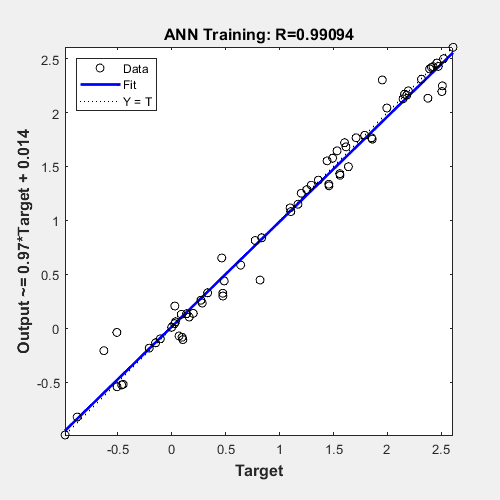

% Use: >> nnstart   or   >> nftool
% • Choose "Fitting" workflow (inputs = [x1; x2], targets = y)
% • Split into train/val/test inside the tool or supply your own split
% • Keep it modest (e.g., 1 hidden layer, ~10 neurons to start)
% • Train, inspect regression plots
% • Export network to workspace as "net", OR export a "results" struct with .Network

% Option A: results struct exported by nftool
% net = results.Network;     % TODO (if exported as 'results')

% Option B: you saved to a .mat file
Sann = load('Lab7ANN.mat');            % TODO
net = Sann.net;            % TODO (ensure this path exists)

% Sanity check:
assert(exist('net','var')==1,'Neural net "net" not found. Export from nftool/nnstart.');

% ---- Evaluate ANN on each split ----
% NOTE: net expects columns, i.e., inputs of size [features x N]
ANNPred_training   = net( training_data_input' )';    % TODO
ANNPred_validation = net( validation_data_input' )';  % TODO
ANNPred_testing    = net( testing_data_input' )';     % TODO

% ---- Quick regression visual check ----
figure; plotregression(ANNPred_training,   training_data_output,   'ANN Training');     % TODO

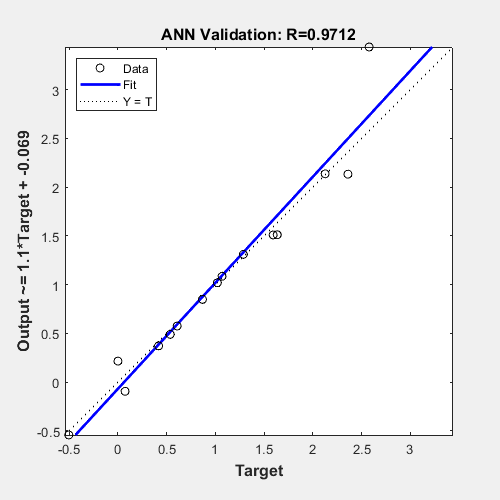

figure; plotregression(ANNPred_validation, validation_data_output, 'ANN Validation');   % TODO

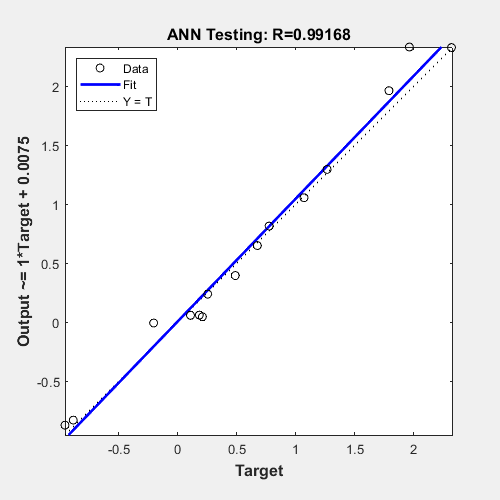

figure; plotregression(ANNPred_testing,    testing_data_output,    'ANN Testing');      % TODO


% ---- Error metrics (Validation set) ----
rmse_ANN = sqrt( mean( (ANNPred_validation - validation_data_output).^2 ) );           % TODO
avg_pct_err_ANN = 100*mean( (ANNPred_validation - validation_data_output) ./ validation_data_output ); % TODO
fprintf('ANN  — RMSE (val): %.4f, Avg %% Error (val): %.2f%%\n', rmse_ANN, avg_pct_err_ANN);

ANN  — RMSE (val): 0.2443, Avg % Error (val): -17.44%


AbsRelErr_ANN = 100*mean( abs(ANNPred_validation - validation_data_output) ./ validation_data_output );
fprintf('ANN — AAVRE (val): %.2f%%\n', AbsRelErr_ANN);

ANN — AAVRE (val): -0.34%


## 5) (Optional) Speed comparison — Surrogates vs. CFD

% Generate 100 random points and time evaluations for each model.
% This illustrates the practical value of surrogates.

numsamples_speed = 100; % 10x10 = 100 points
xr1 = x1_min + (x1_max - x1_min).*rand(numsamples_speed,1);   % TODO
xr2 = x2_min + (x2_max - x2_min).*rand(numsamples_speed,1);   % TODO

% --- RSM timing ---
tic;
y_rsm = rsm_fun(xr1, xr2, beta);      % TODO
t_rsm = toc;

% --- ANN timing ---
tic;
y_ann = net([xr1 xr2]')';             % TODO
t_ann = toc;

fprintf('Eval time (100 pts): RSM = %.6f s, ANN = %.6f s\n', t_rsm, t_ann);

Eval time (100 pts): RSM = 0.005717 s, ANN = 0.059914 s


## 6) (Homework — Task 3) Optimization with Surrogates  

% Using the fast surrogates, find (x1, x2) that minimize the response.
%  • Keep the search inside the bounds [-2,2] x [-1,1].
%  • You can add a soft penalty if you use unconstrained solvers like fminsearch.
%
% Example outline (do NOT run here; complete as homework):
%
penalty = @(x) 1e6 * any([x(1) < x1_min, x(1) > x1_max, x(2) < x2_min, x(2) > x2_max]);
f_RSM = @(x) rsm_fun(x(1), x(2), beta) + penalty(x);
x0 = [0, 0];  % initial guess
[xstar_RSM, fval_RSM] = fminsearch(f_RSM, x0);
%
f_ANN = @(x) net(x') + penalty(x);
[xstar_ANN, fval_ANN] = fminsearch(f_ANN, x0);
%
% Compare surrogate optima and (optionally) verify by running giant_CFD_code at those points.
fprintf('\n');
fprintf('RSM Optimum (fminsearch):\n');

RSM Optimum (fminsearch):


fprintf('  x* = [%.4f, %.4f]\n', xstar_RSM(1), xstar_RSM(2));

  x* = [0.3810, -1.0000]


fprintf('  f(x*) = %.4f\n', fval_RSM);

  f(x*) = -0.9295


fprintf('\n');
fprintf('ANN Optimum (fminsearch):\n');

ANN Optimum (fminsearch):


fprintf('  x* = [%.4f, %.4f]\n', xstar_ANN(1), xstar_ANN(2));

  x* = [-0.1685, 0.7518]


fprintf('  f(x*) = %.4f\n', fval_ANN);

  f(x*) = -1.4493


fprintf('\n');


## 7) (Optional) Visualization helpers (fill in if you want a surface plot)

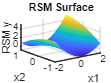

% Make a mesh over the design space and visualize the RSM/ANN surfaces.
[X1, X2] = meshgrid(linspace(x1_min,x1_max,50), linspace(x2_min,x2_max,50));  % TODO
Y_rsm = rsm_fun(X1, X2, beta);                                                % TODO
figure; surf(X1, X2, Y_rsm); xlabel('x1'); ylabel('x2'); zlabel('RSM y'); title('RSM Surface'); shading interp;

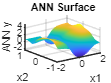

Y_ann = net([X1(:) X2(:)]'); Y_ann = reshape(Y_ann, size(X1));                % TODO
figure; surf(X1, X2, Y_ann); xlabel('x1'); ylabel('x2'); zlabel('ANN y'); title('ANN Surface'); shading interp;

## End of script

% Checklist before you move on:
%  [ ] DOE filled and CFD outputs computed
%  [ ] Data split into train/val/test
%  [ ] RSM coefficients (beta) obtained and evaluated
%  [ ] ANN trained, exported to 'net', and evaluated
%  [ ] Error metrics reported on validation set
%  [ ] (Optional) Speed test & visualizations
%  [ ] (Homework) Optimization with surrogates
